# Simulink Test Manager

The purpose of this work was to develop a testing method in MOBATSim to verify that changes in the model do not affect the different scenarios outcome.

Different than in the Model-basedTesting there are no single model components tested and therefore must not be isolated by a Test Harness Model. The tool Simulink Test Manager is to create and manage test cases and run test cases to execute tests. Logical and Temporal Assessments in Simulink® Test™ are used to verify the scenarios requirements. Functional Requirements are only made for a better overview of the things that need to be tested in each scenario.

## Table of Contents

## I     Simulink® Test™ - Overview

Simulink® Test™ provides tools for authoring, managing, and executing systematic, simulation-based tests of models, generated code, and simulated or physical hardware. It includes simulation, baseline, and equivalence test templates that let you perform functional, unit, regression, and back-to-back testing using software-in-the-loop (SIL), processor-in-the-loop (PIL), and real-time hardware-in-the-loop (HIL) modes.

With Simulink Test you can create nonintrusive test harnesses to isolate the component under test. You can define requirements-based assessments using a text-based language, and specify test input, expected outputs, and tolerances in a variety of formats, including Microsoft® Excel®. Simulink Test includes a Test Sequence block that lets you construct complex test sequences and assessments, and a test manager for managing and executing tests. Observer blocks let you access any signal in the design without changing the model or the model interface. Large sets of tests can be organized and executed in parallel or on continuous integration systems.

You can trace tests to requirements (with Simulink Requirements™) and generate reports that include test coverage information from Simulink Coverage™.

## II    Test Authoring

Start authoring tests by creating a test file in the Test Manager. Add test suites (1) for different test scenarios and test cases (2) for where you can create verification statements (Assessments) that run with your model and code.

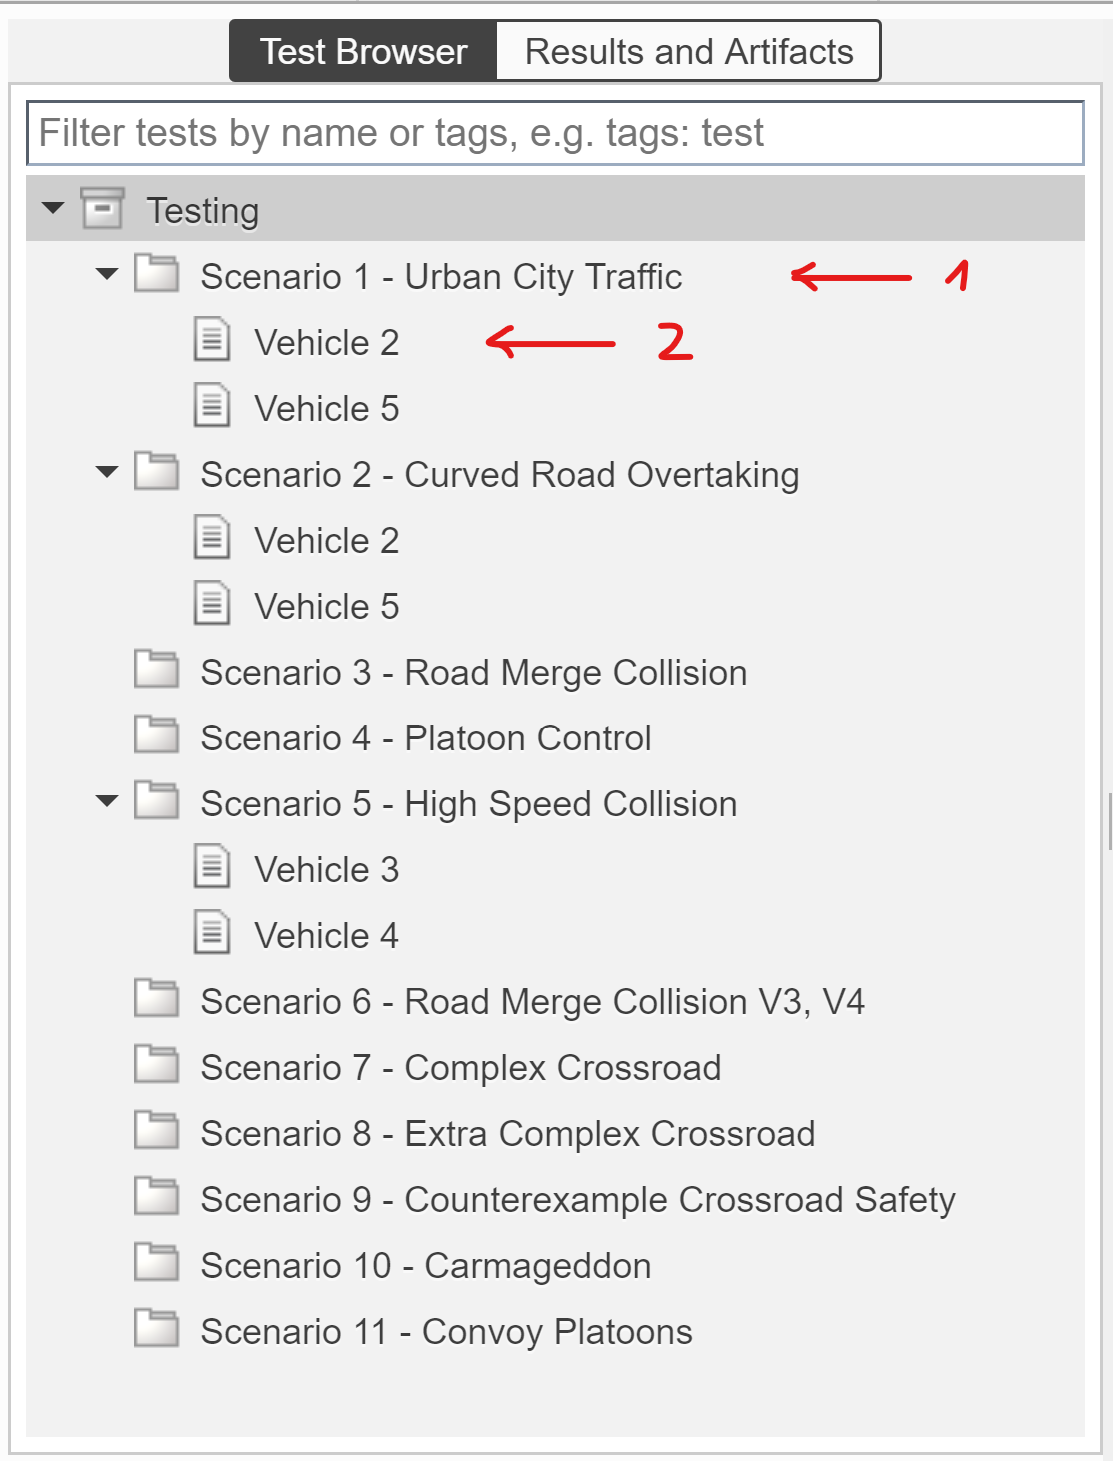

A test file can insist of multiple test suites (Szenarios). Test suites then contain the test cases. Click right on a test case to choose between four different tests: Baseline-, Equivalence-, Simulation-, and Realtime Test.

We only require the model to simulate without errors, so we will run a **Simulation Test**. The simulation test is useful if the model is still in development, or if you have an existing test model that contains inputs and assessments and logs relevant data. Using the Test Manager to run simulation tests allows you to manage numerous tests and to capture and manage results systematically.

- **!** By default, running a test in the Test Manager **disables breakpoints** for Simulink, Stateflow®, and Test Sequence blocks. Use **Run with Stepper** in the Test Manager to run a test in the simulation stepper and use the breakpoints. **!**

### **Link Test Cases**

If you use many test cases (szenarios), link to each specific test case to distinguish which blocks and test steps apply to it. To link test cases to requirements and Simulink blocks,

- Open the test case in the Test Manager.

- In the left pane, in the **Test Browser** tab, select the test case.

- In Simulink in the **Apps** tab, click **Requirements Manager**.

- To link a test case to a:

- Simulink block, right-click the block in de Simulink Model and select **Requirements** > **Link to Current Test Case** from the context menu.

- Requirement, right click on the requirement and select **Link from Selected Test Case **from the context menu.

- **or **with drag and drop 

**Info:** Requirements can be linked to Test Cases, Test Suites and/or the whole test file.

Implementation and Verification status are displayed by beams in different colors:

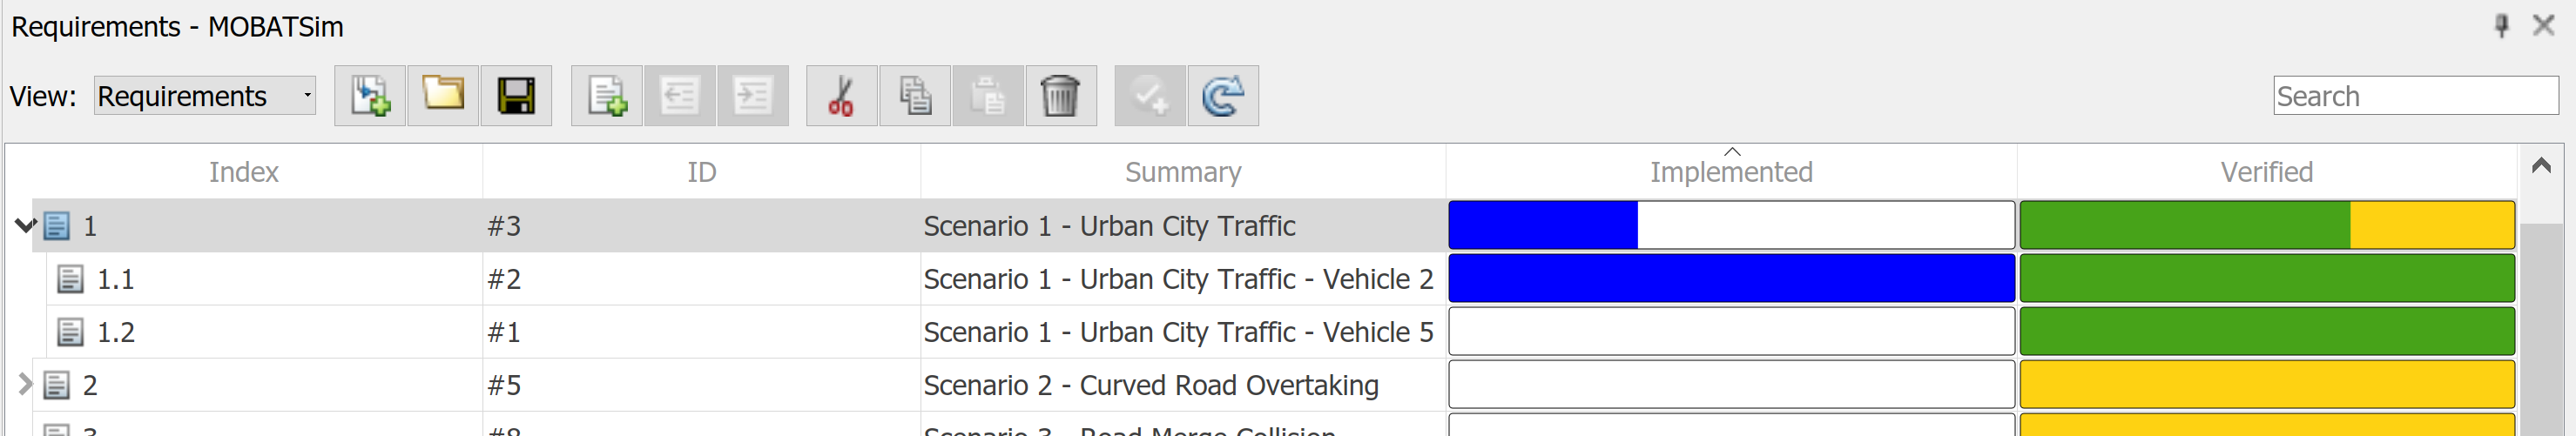

### Overview

The following image shows how a Simulation Test is structured in the Simulink® Test™ Manager:

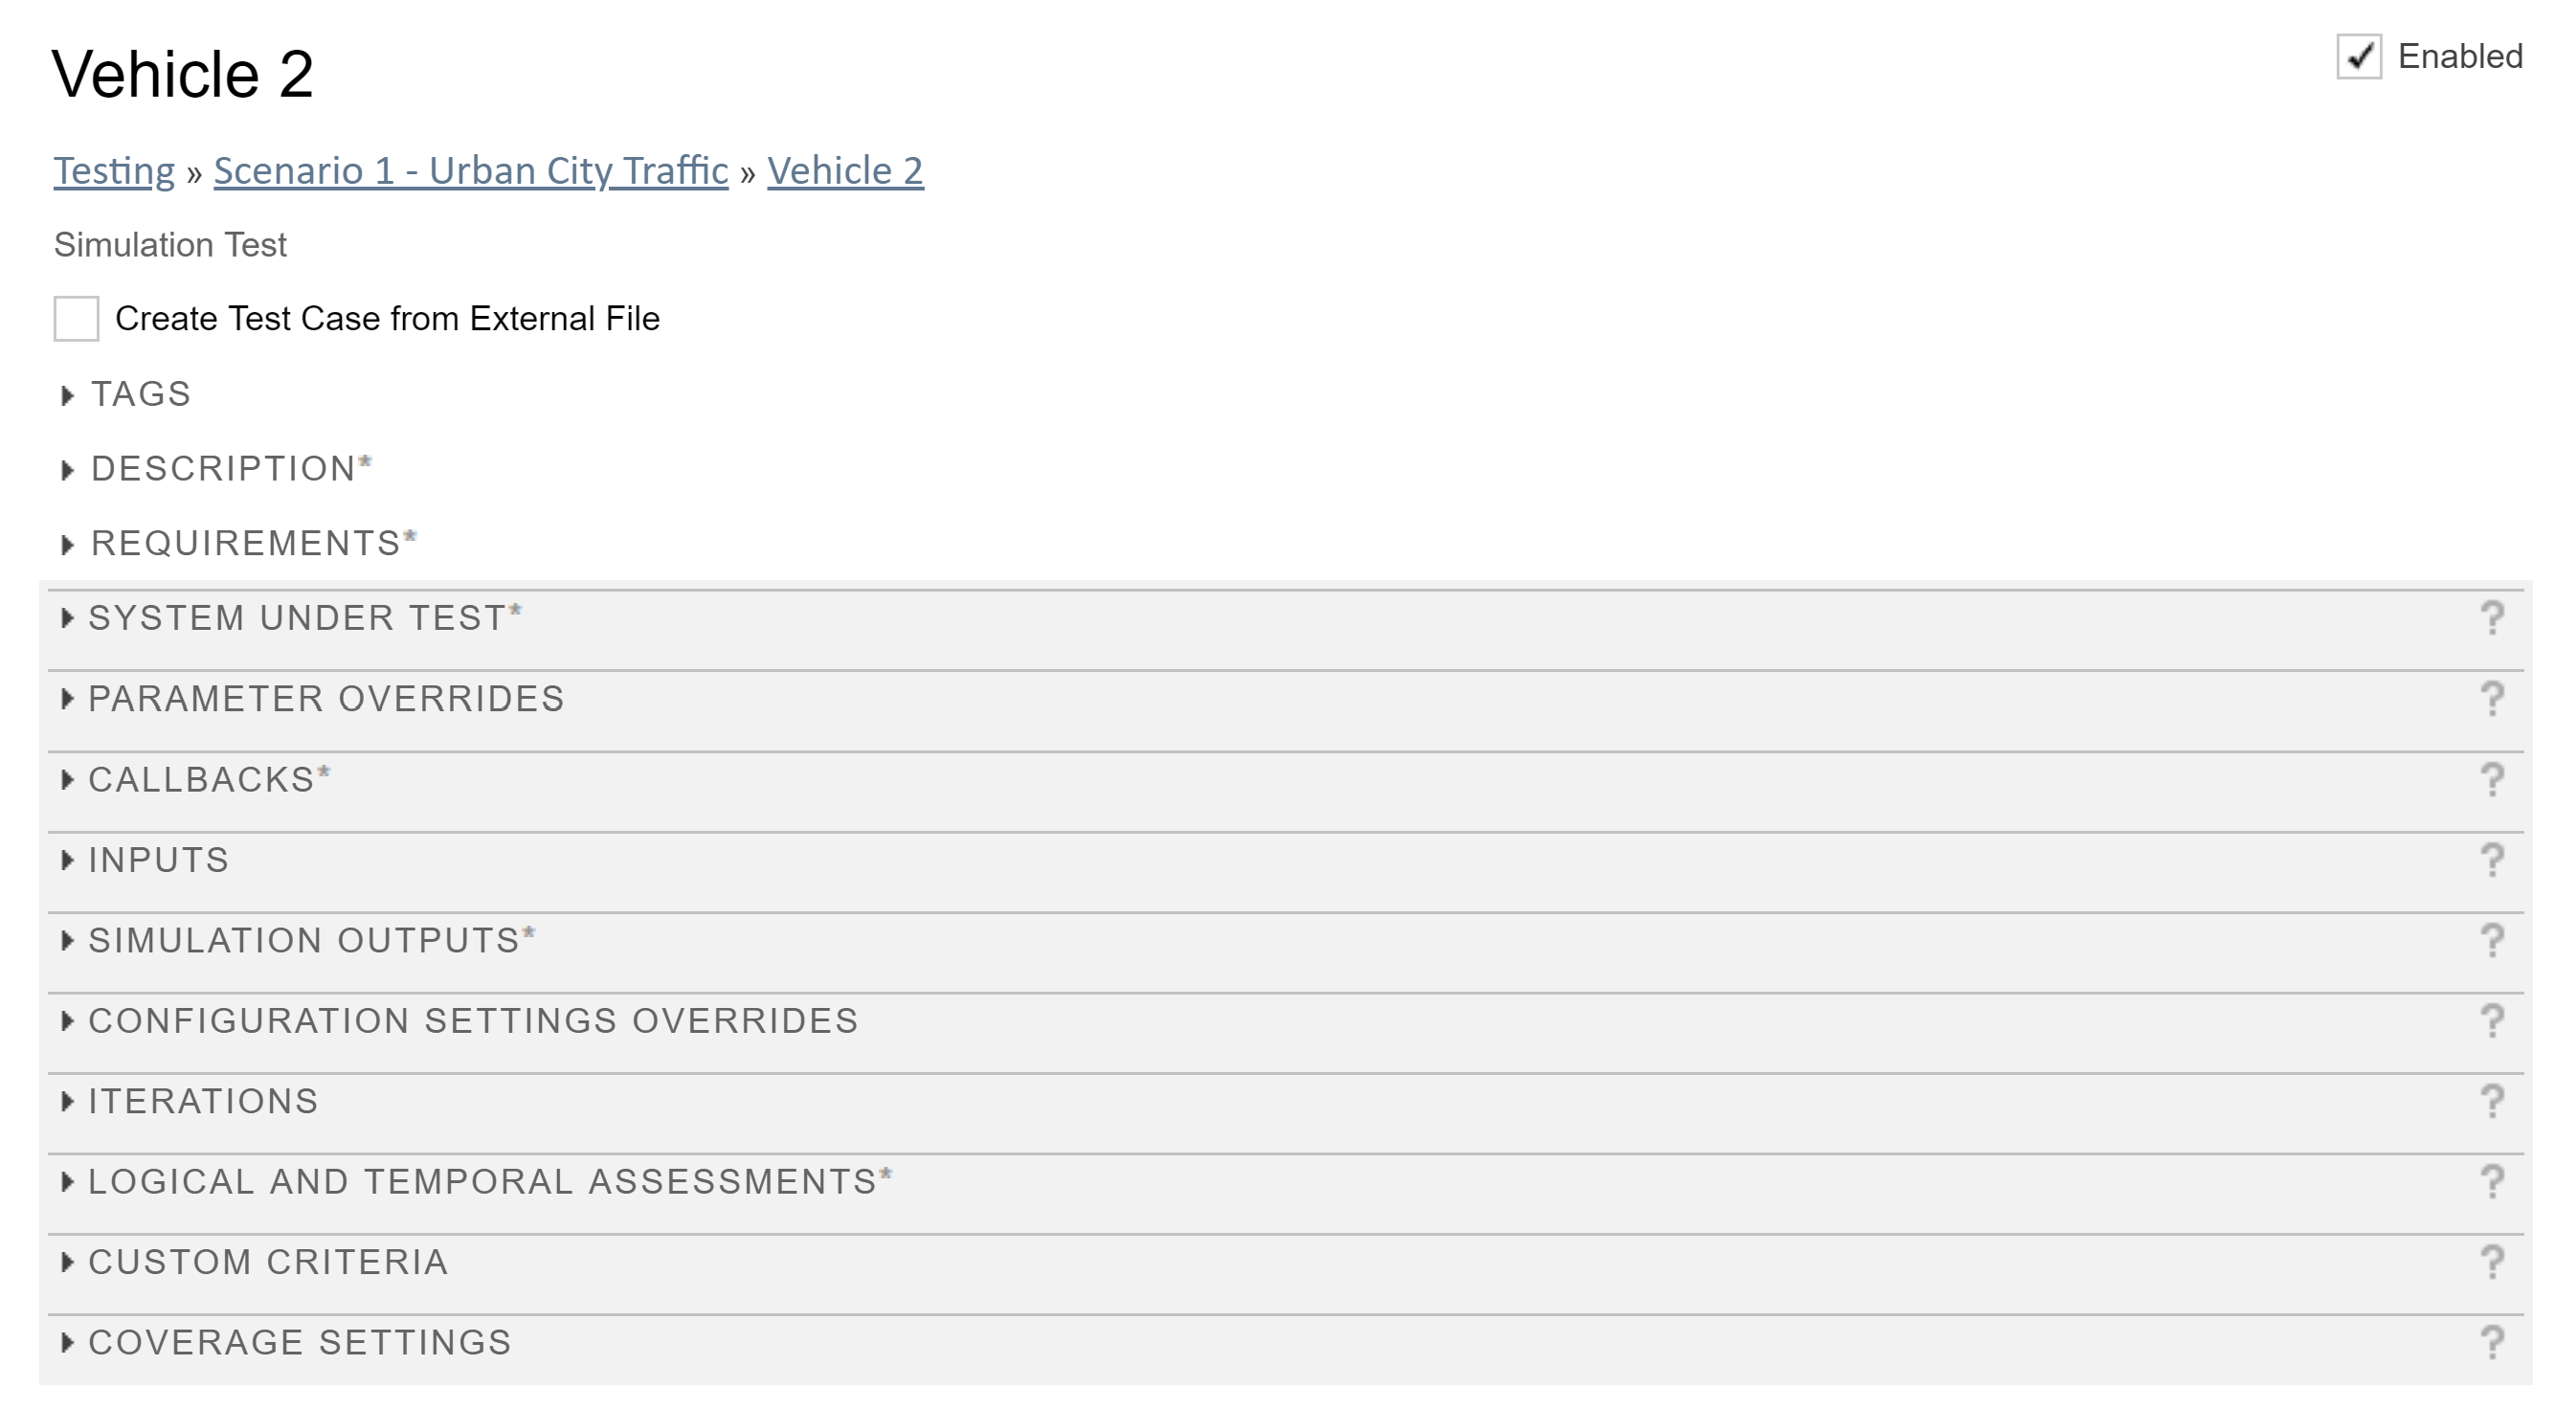

- TAGS: to filter tests when executing tests or viewing results

- REQUIREMENTS: linked requirements for better distingushing between test scenarious as described here.

- SYSTEM UNDER TEST: Choose model you want to simulate.

- **Hint:** Select 'SIMULATION SETTINGS AND RELEASE OVERRIDES' to change Simulation time, if you don't need to simulate the whole period.

- CALLBACKS: run **pre-load callback** to make sure workspace is empty and start the desired scenario: 

clear all;
prepare_simulator("scenarioName","Urban City Traffic");

- INPUTS: Define input data 

- SIMULATION OUTPUTS: Define signal outputs. They can be viewed with the Visualize button in the register or in the results and artifacts tab next to the test browser.                                                                

**Hint: Only signals** can be plotted. No simulation output of variables/data possible.

- LOGICAL AND TEMPORAL ASSESSMENTS: Assessing simulation behavior. More information how to use in the next section.

### Logical and Temporal Assessments

Functional testing includes assessing simulation behavior and comparing simulation data to expected results. You can assess simulation behavior by:

- **Using temporal and logical assessments in a test case *****- can be done without modifying the model***

- Including `verify` statements and other operators in a Test Assessment or Test Sequence block - *model needs to be modified*

- Using blocks from the Model Verification library *- model needs to be modified*

**How to work with assessments:**

- Create or open a test case in the Test Manager.

- Navigate to the **Logical and Temporal Assessments** Editor.

- Click **Add Assessment**. 

Simulink® Test™ provides two logical and one temporal assessment templates:

#### **Logical Assessment Templates**

                -    **Custom** — Check if a logical expression holds true for all time steps.

                -    **Bounds Check** — Check maximum and minimum bounds for signals and expressions

#### **Temporal Assessment Template**

**                -    Trigger-Response —** Check for a signal response when a trigger is detected

        4. Select an assessment template (Bounds Check, Custom or Trigger-response)

        5. Enter the assessment conditions.

- Map symbols to model elements, such as signals, time series, or constant. How to define symbols and variables is explained in the next section.

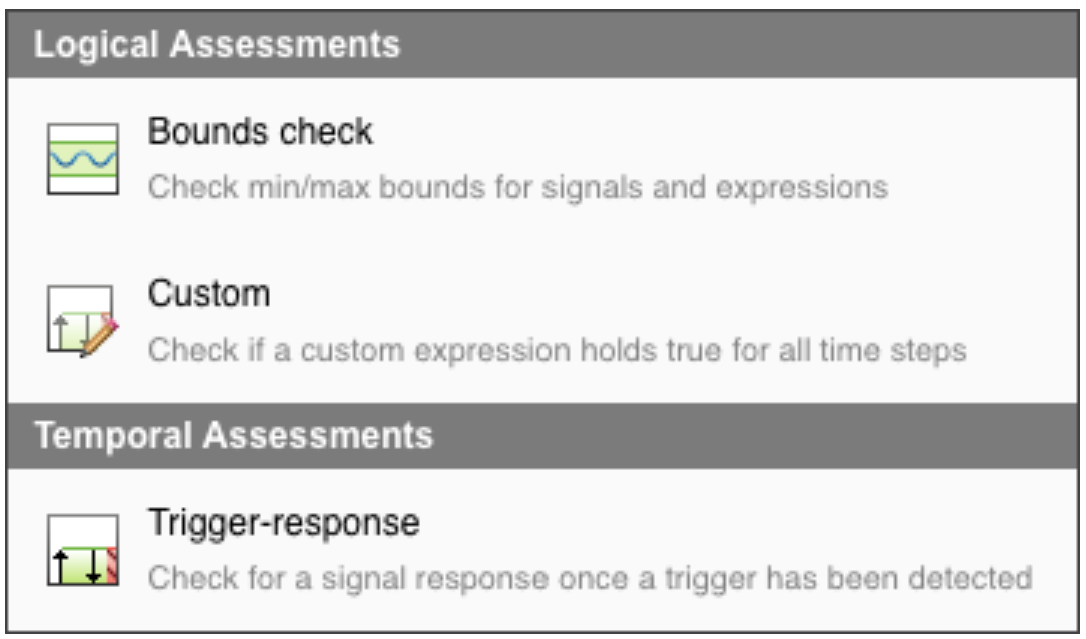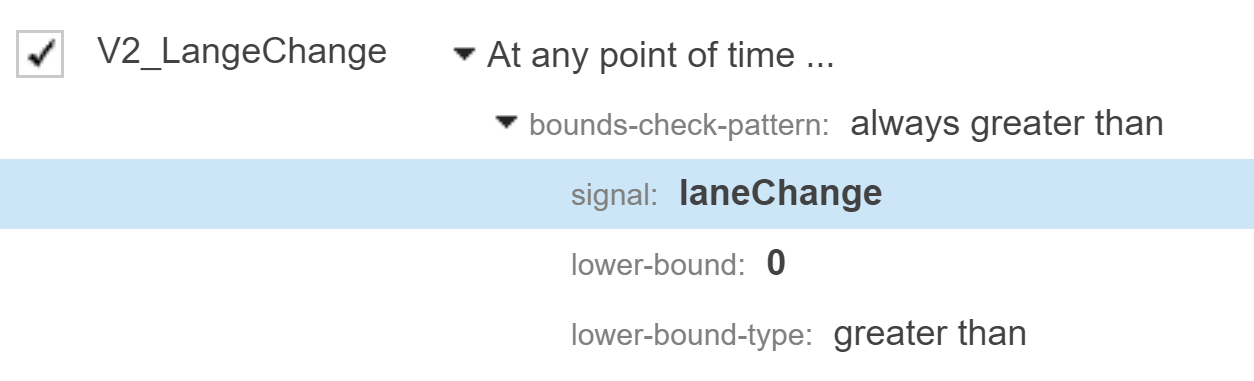

In the image above a **Bounds Check Assessment** was used to check whether the **signal laneChange** is always greater than 0. Note that statements must be true **at any point of time **for passing the test!

         6.  Run the test case.

         7.  View results in the tab '**Results and Artifacts**'

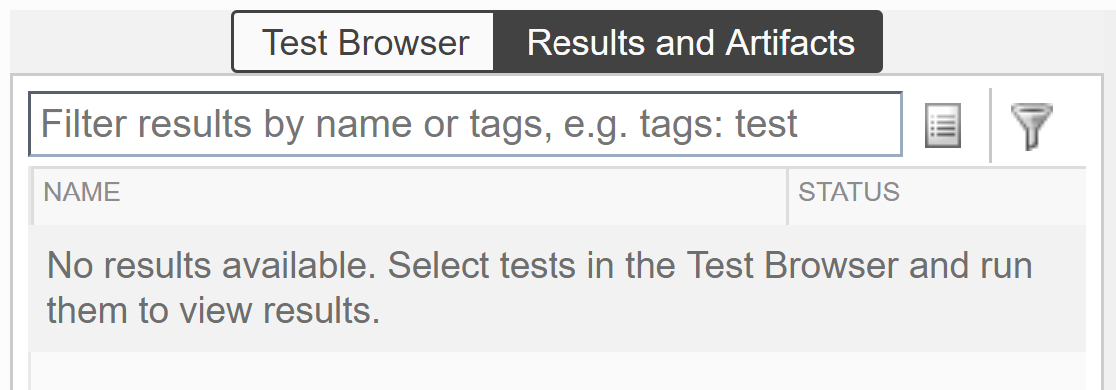

#### **Data Types in Assessment Conditions**

Logical and temporal assessment conditions support the data types listed on [Data Types Supported by Simulink](https://de.mathworks.com/help/simulink/ug/data-types-supported-by-simulink.html), with the exception of `string`. All operands in an assessment condition must be of the same data type. 

### Symbols in Assessments

In an assessment condition you can use signals, expressions, etc. from your model. In Simulink all operands must be defined as a 'Symbol' on the right side before using them. There are two ways how to resolve symbols in Simulink: Defining Variables in the Assessment Callback Section and Mapping Variables to the Model

#### **Define Variables in the Assessment Callback Section**

The **Assessment Callback** section allows you to define variables that you can use in logical and temporal assessment conditions and expressions. You can define variables the same way you do in the MATLAB workspace. This callback also has access to predefined variables that contain data from your test, model, and simulation, such as a signal from a Simulink block. You can define a variable as a function of this data.

For use in assessment conditions and expressions you need to map the symbols to the defined variables from the Callback Section: 

- On the Symbols pane click **Map to expression **

- Assign the variable defined in the Callback section

Note: The name of the symbol is the one to use for the assessment!

Note: Because the `t` symbol is automatically bound to the simulation time, you do not need to map it to an expression. `t` is not visible in the **Symbols** pane.

The variables created in the **Assessment Callback** section can only be used in conditions and expressions in the **Logical and Temporal Assessments** pane. These variables cannot be used in other areas of the Test Manager. The **Assessment Callback** is saved as part of the test file and is only resolved once at the end of simulation time.

#### **Map Symbols to model element**

You can also map symbols directly to model elemts (signals, parameters or blocks in the system under test).

- On the Symbols pane click **Map to model element **-> The simulink model will open

- Navigate to the block including your signal and select it from the drop-down list that appears when clicking on a block in the model.

- After you finish mapping symbols to model elements, the **Symbols** pane displays metadata that corresponds to the model element.

Note: You can only refer to signals that have an Input/ Output port **or** are included in the base workspace of a block. You can not reach other variables or functions defined inside the script of this block. Try using the Callback section instead.

## III    Limitations - Overview

- In the Assessment Callback it is only possible to access signals, varibales, etc. **at the end** of simulation time. 

- Therefore variables assessed with the Assessment Callback can **not be plotted**.

- Assessments only allow to verify always *true* statements. Sometimes it might be difficult to form statements this way.

- The symbols can be mapped to signals that are either input/output of a block or are in the base workspace of that block.

- Simulink Test might become more useful when it manages a great amount of test cases by keeping the overview intuitve. For only a few tests the effort might be too big.

## IV    Future Ideas

- Have a look on the stepper inside the test manager. It might be useful to access variables during the simulation. See point 1 at Limitations.

- Consider whether and to what extend a test harness block affects the simulation time.